**Acoustic Modem Decoder**

% load short_modem_rx.mat
% load long_modem_rx.mat
% load custom_modem_rx.mat
load custom_modem_rx_quad_may4th_prosper.mat

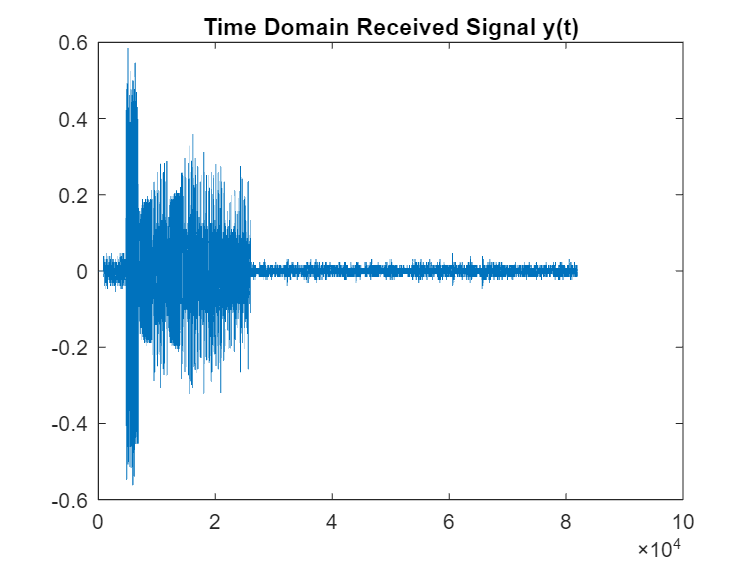

plot(y_r)
title("Time Domain Received Signal y(t)")
saveas(gcf, "1. Time Domain Received Signal.png")


start_idx = find_start_of_signal(y_r,x_sync);
y_t = y_r(start_idx+length(x_sync):end);

bits_per_char = 8;
SymbolPeriod = 100;
y_t = y_t(1:msg_length*bits_per_char*SymbolPeriod);

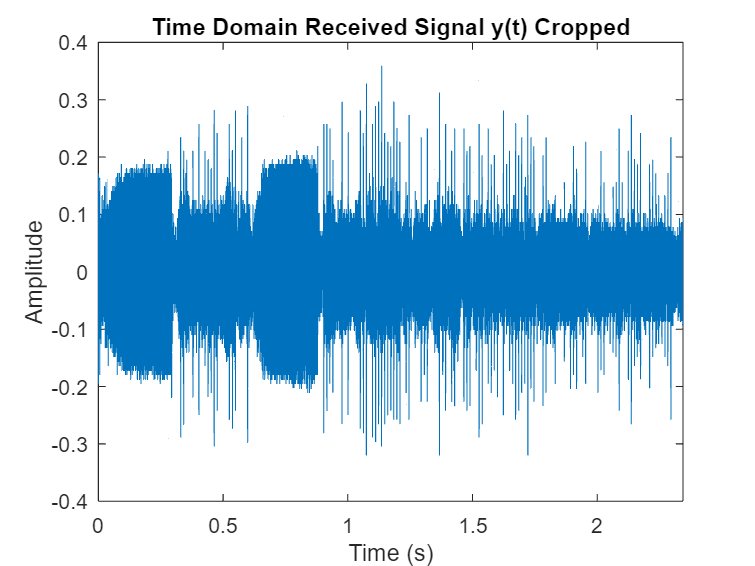

t = [0:length(y_t)-1]./Fs;

plot_time_graph(t, y_t);
title("Time Domain Received Signal y(t) Cropped")
saveas(gcf, "2. Time Domain Received Signal Cropped.png")

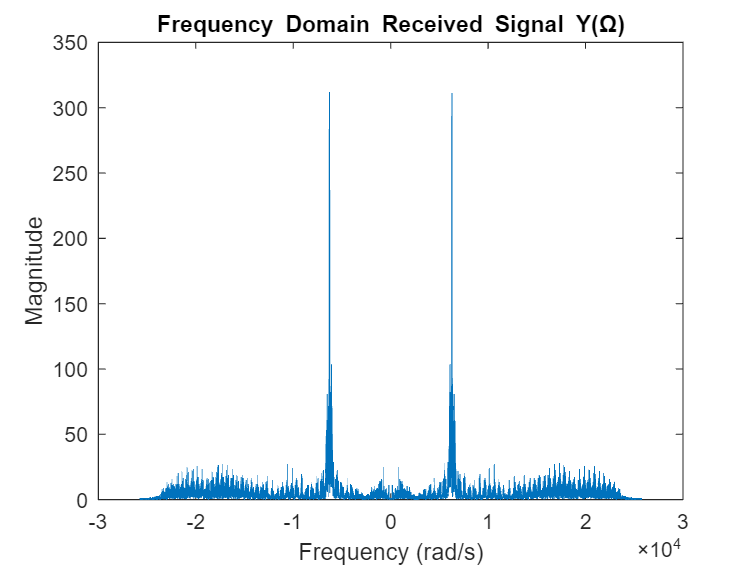


plot_ft_rad(y_t, Fs);
title("Frequency Domain Received Signal Y(\Omega)")
saveas(gcf, "3. Frequency Domain Received Signal.png")

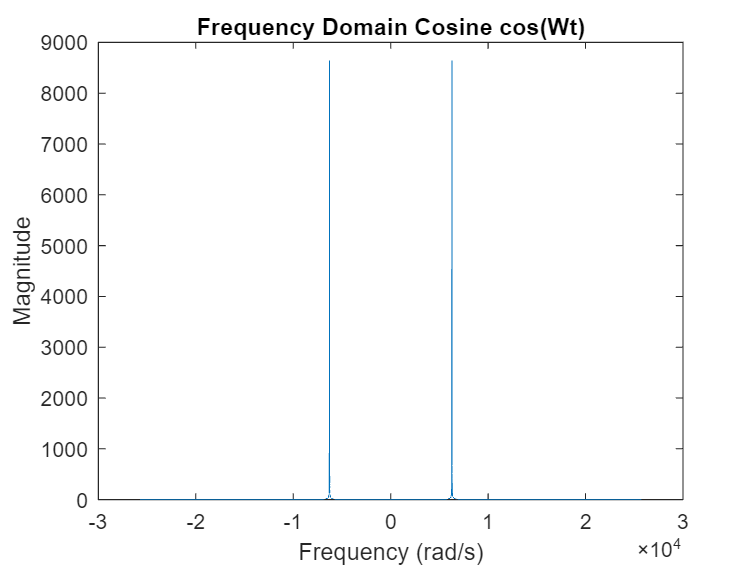

W = 2*pi*f_c; % cutoff frequency of lowpass filter and frequency of cosine
cosine_signal = cos(W*t');
sine_signal = sin(W*t');
% sine_signal = sin(3*W*t');

plot_ft_rad(cosine_signal, Fs);
title("Frequency Domain Cosine cos(Wt)")
saveas(gcf, "5. Frequency Domain Cosine.png")

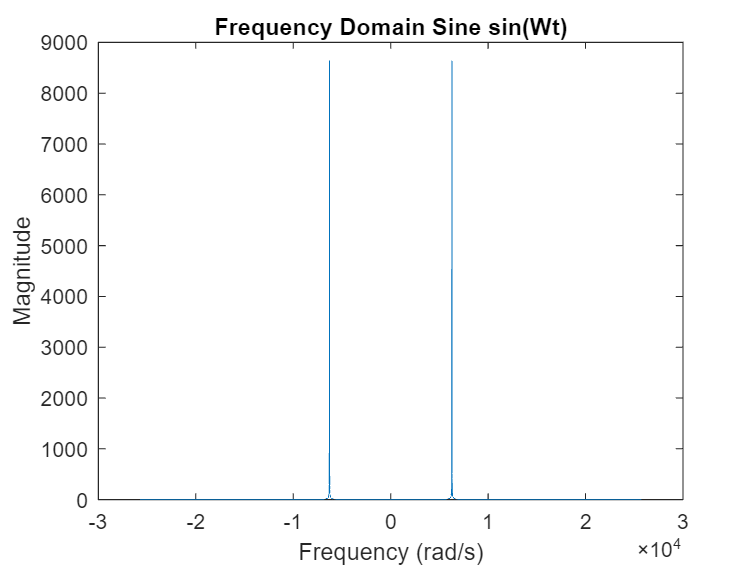


plot_ft_rad(sine_signal, Fs);
title("Frequency Domain Sine sin(Wt)")
saveas(gcf, "5.5 Frequency Domain Sine.png")

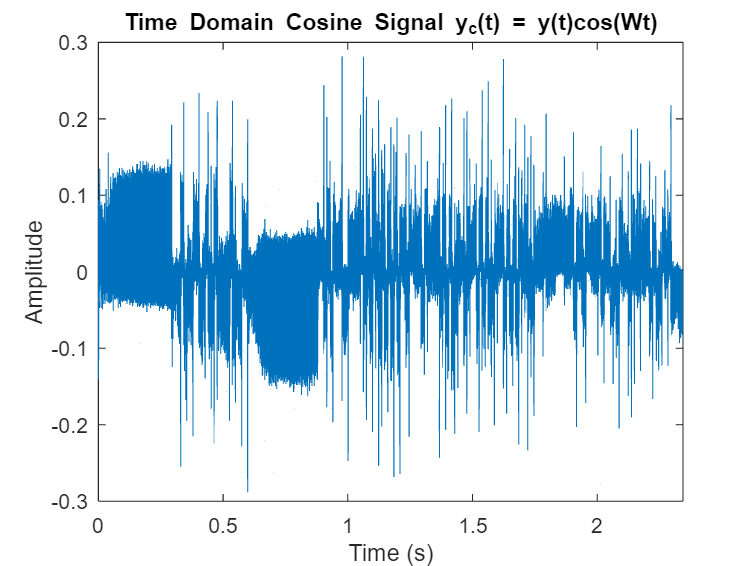

y_c = y_t.*cosine_signal;

plot_time_graph(t, y_c);
title("Time Domain Cosine Signal y_{c}(t) = y(t)cos(Wt)")
saveas(gcf, "6. Time Domain Cosine Signal yc.png")

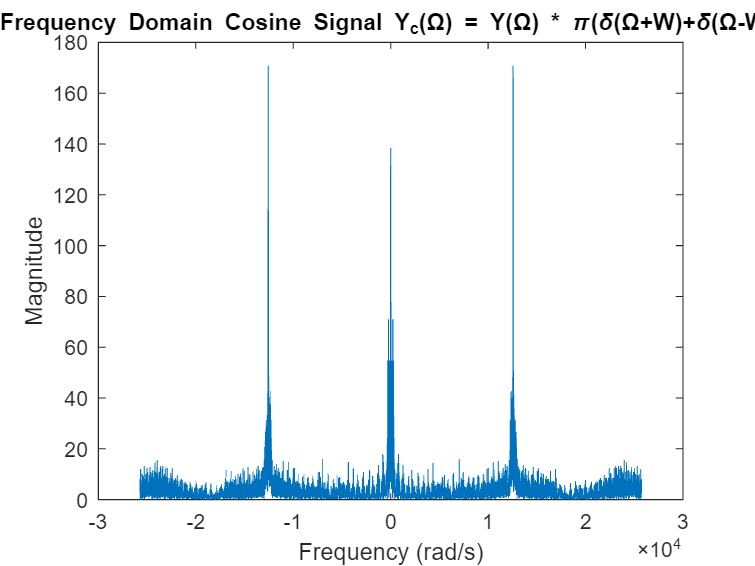


plot_ft_rad(y_c, Fs);
% title("Frequency Domain Cosine Signal Y_{c}(\Omega) = Y(\Omega) * FT(cos(2\pif_{c}t))")
title("Frequency Domain Cosine Signal Y_{c}(\Omega) = Y(\Omega) * \pi(\delta(\Omega+W)+\delta(\Omega-W))")
saveas(gcf, "7. Time Domain Cosine Signal Yc.png")

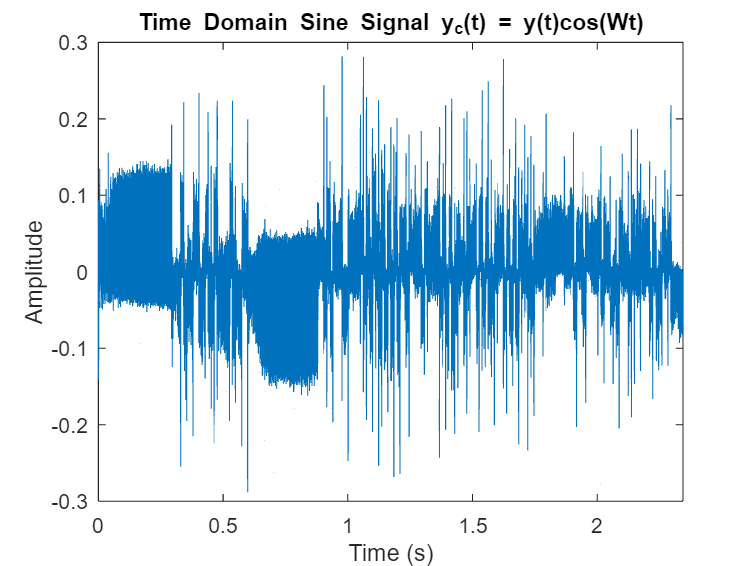

y_s = y_t.*sine_signal;

plot_time_graph(t, y_c);
title("Time Domain Sine Signal y_{c}(t) = y(t)cos(Wt)")
saveas(gcf, "6.5 Time Domain Sine Signal yc.png")

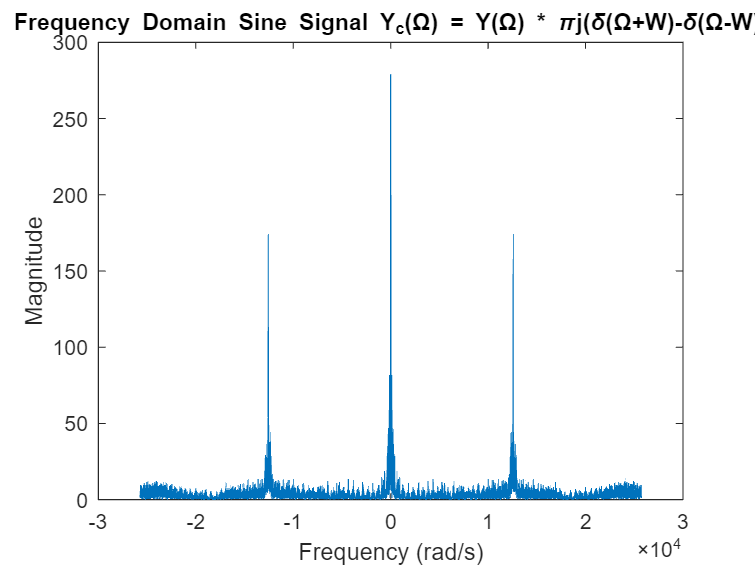


plot_ft_rad(y_s, Fs);
% title("Frequency Domain Sine Signal Y_{c}(\Omega) = Y(\Omega) * FT(sin(2\pif_{c}t))")
title("Frequency Domain Sine Signal Y_{c}(\Omega) = Y(\Omega) * \pij(\delta(\Omega+W)-\delta(\Omega-W))")
saveas(gcf, "7.5 Time Domain Sine Signal Yc.png")

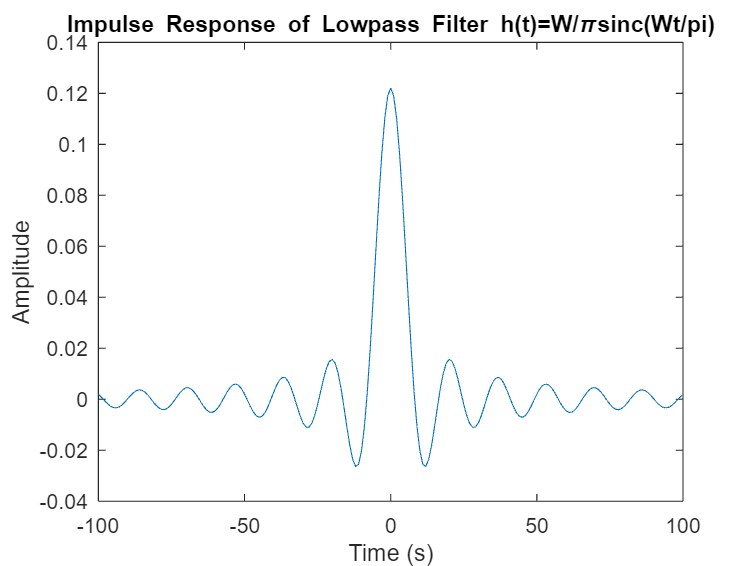

n = 100;
tt = [-n:n];
% h = W/pi/Fs*sinc(W/pi/Fs*tt');
h = f_c/Fs*sinc(f_c/Fs*tt'); % What is the right cutoff freq for lowpass?

plot_time_graph(tt, h);
title('Impulse Response of Lowpass Filter h(t)=W/\pisinc(Wt/pi)');
saveas(gcf, "8. Impulse Response of Lowpass Filter.png")

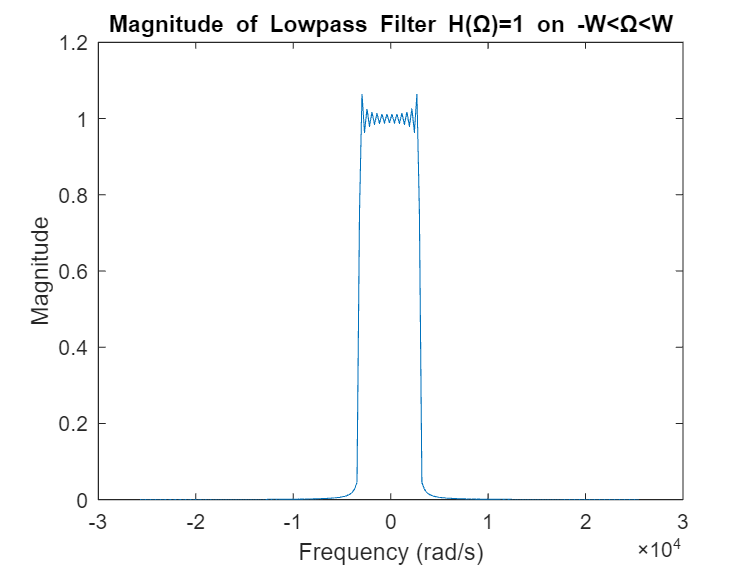


plot_ft_rad(h, Fs);
title('Magnitude of Lowpass Filter H(\Omega)=1 on -W<\Omega<W');
saveas(gcf, "9. Magnitude of Lowpass Filter.png")

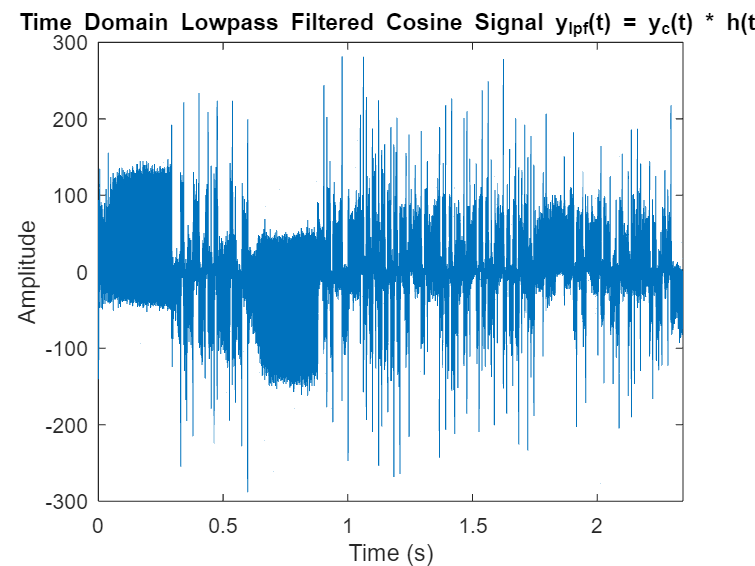

y = conv(y_c, h); % convolve to filter

y_c_lpf = y(n+1:end-n);

plot_time_graph(t, y_c_lpf);
title("Time Domain Lowpass Filtered Cosine Signal y_{lpf}(t) = y_{c}(t) * h(t)")
saveas(gcf, "10. Time Domain Lowpass Filtered Cosine Signal.png")

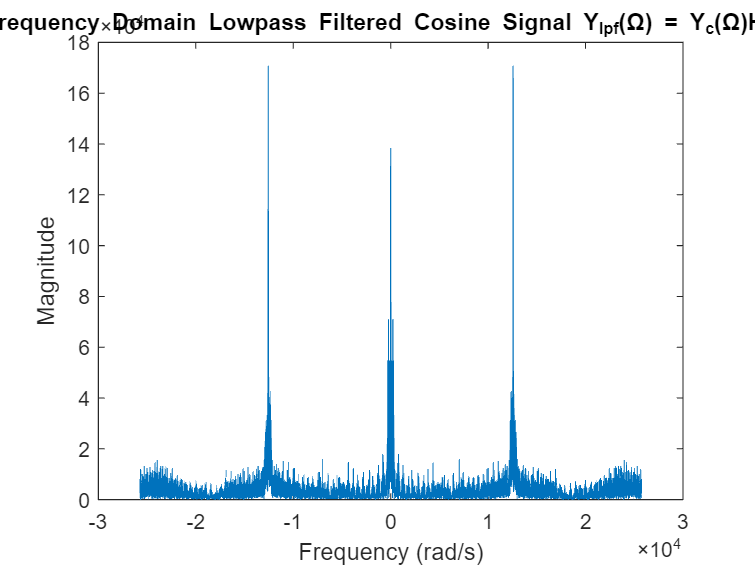


plot_ft_rad(y_c_lpf, Fs); % plot the magnitude of the FT
title("Frequency Domain Lowpass Filtered Cosine Signal Y_{lpf}(\Omega) = Y_{c}(\Omega)H(\Omega)")
saveas(gcf, "11. Frequency Domain Lowpass Filtered Cosine Signal.png")

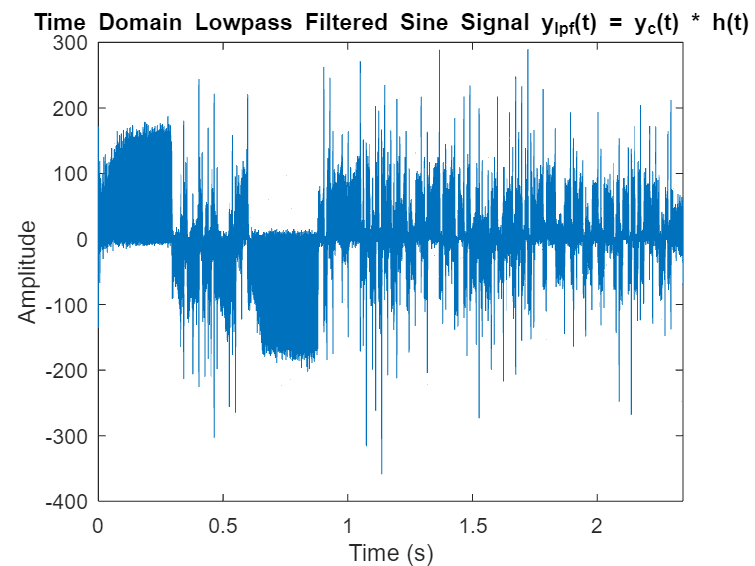

y = conv(y_s, h); % convolve to filter

y_s_lpf = y(n+1:end-n);

plot_time_graph(t, y_s_lpf);
title("Time Domain Lowpass Filtered Sine Signal y_{lpf}(t) = y_{c}(t) * h(t)")
saveas(gcf, "10.5 Time Domain Lowpass Filtered Sine Signal.png")

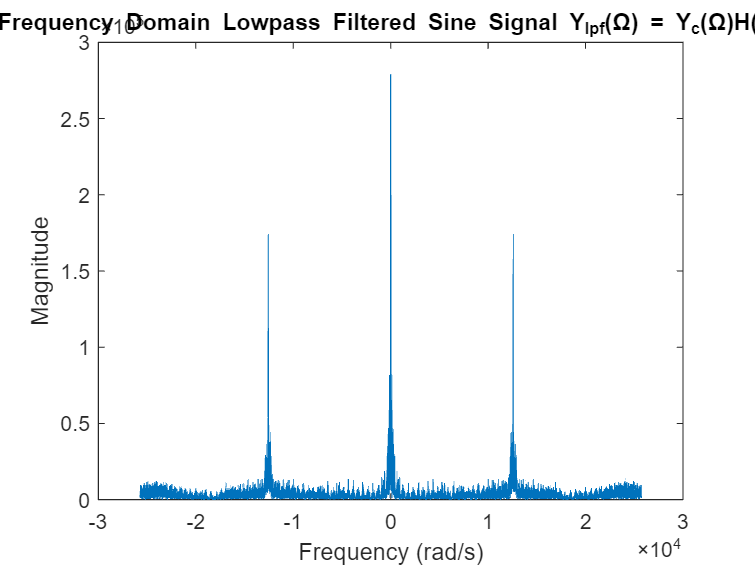


plot_ft_rad(y_s_lpf, Fs); % plot the magnitude of the FT
title("Frequency Domain Lowpass Filtered Sine Signal Y_{lpf}(\Omega) = Y_{c}(\Omega)H(\Omega)")
saveas(gcf, "11.5 Frequency Domain Lowpass Filtered Sine Signal.png")

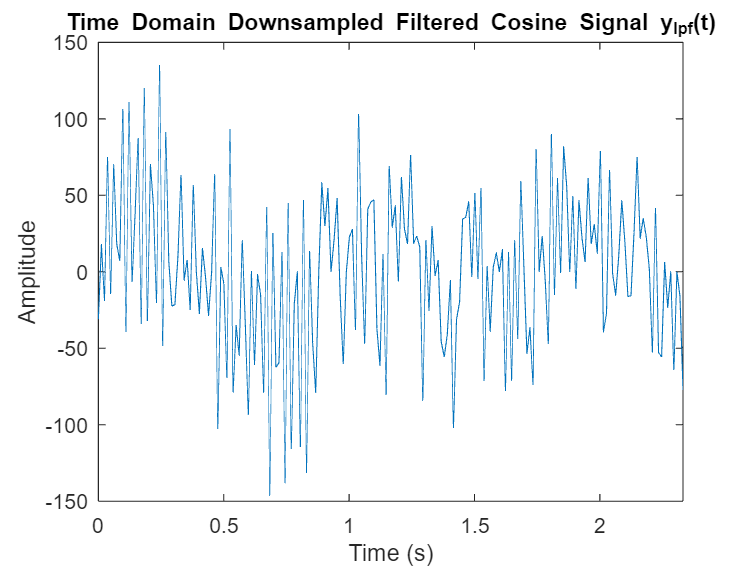

y_c_dn = downsample(y_c_lpf(SymbolPeriod/2:end), SymbolPeriod);
y_s_dn = downsample(y_s_lpf(SymbolPeriod*0.4:end), SymbolPeriod);
t_dn = downsample(t, SymbolPeriod);

plot_time_graph(t_dn, y_c_dn)
title("Time Domain Downsampled Filtered Cosine Signal y_{lpf}(t)")
saveas(gcf, "12. Time Domain Downsampled Filtered Cosine Signal.png")

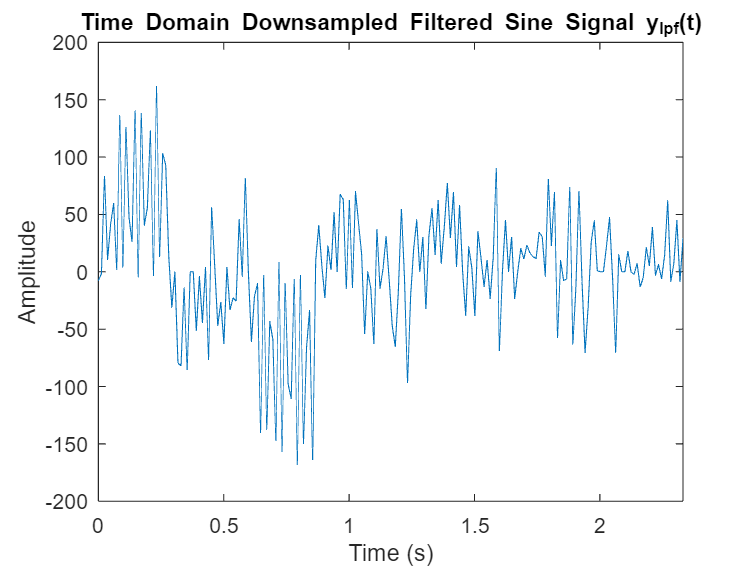


plot_time_graph(t_dn, y_s_dn)
title("Time Domain Downsampled Filtered Sine Signal y_{lpf}(t)")
saveas(gcf, "12.5 Time Domain Downsampled Filtered Sine Signal.png")


% depending on sign:
% message_c = y_c_dn > 0;
% message_s = y_s_dn > 0;
message_c = y_c_dn < 0;
message_s = y_s_dn < 0;
% convert to a string assuming that x_d is a vector of 1s and 0s representing the decoded bits
BitsToString(message_c)

ans = 'óa□"ä#e□tÐ*äZ%□u©Li□}Î□!'

BitsToString(message_s)

ans = 'Í□zeih?!f{a□b #rwt°ar`!X'

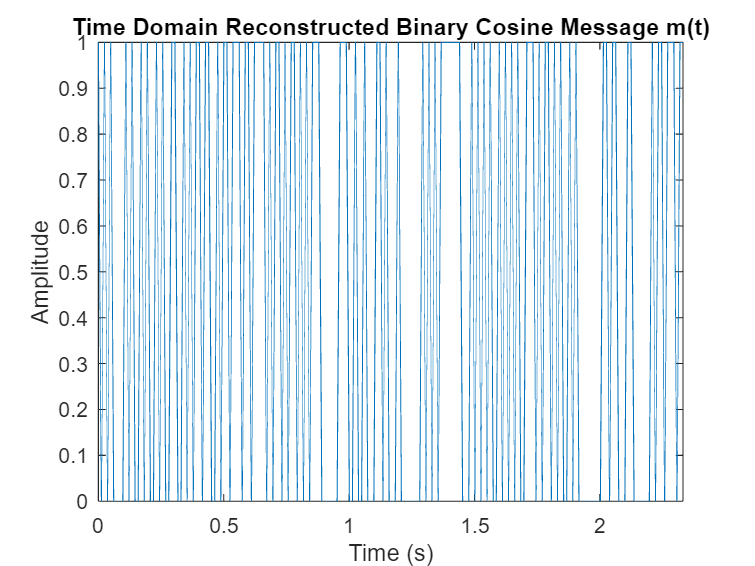


plot_time_graph(t_dn, message_c)
title("Time Domain Reconstructed Binary Cosine Message m(t)")
saveas(gcf, "13. Time Domain Reconstructed Binary Cosine Message.png")

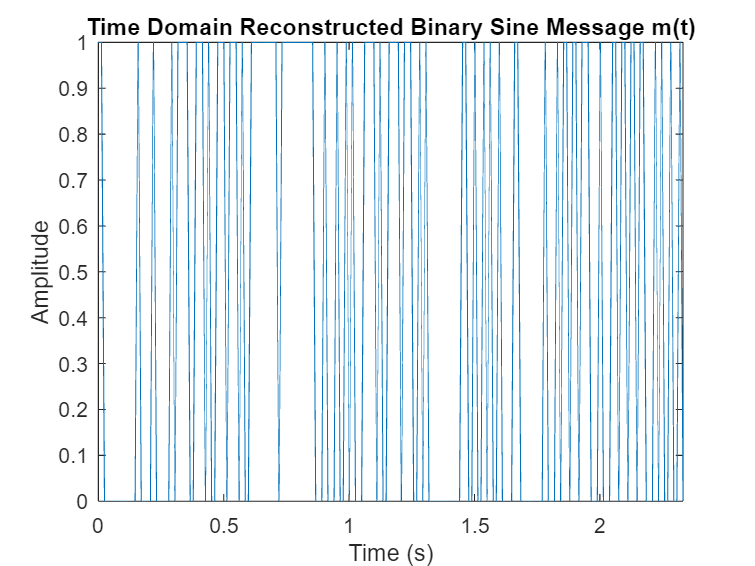


plot_time_graph(t_dn, message_s)
title("Time Domain Reconstructed Binary Sine Message m(t)")
saveas(gcf, "13.5 Time Domain Reconstructed Binary Sine Message.png")

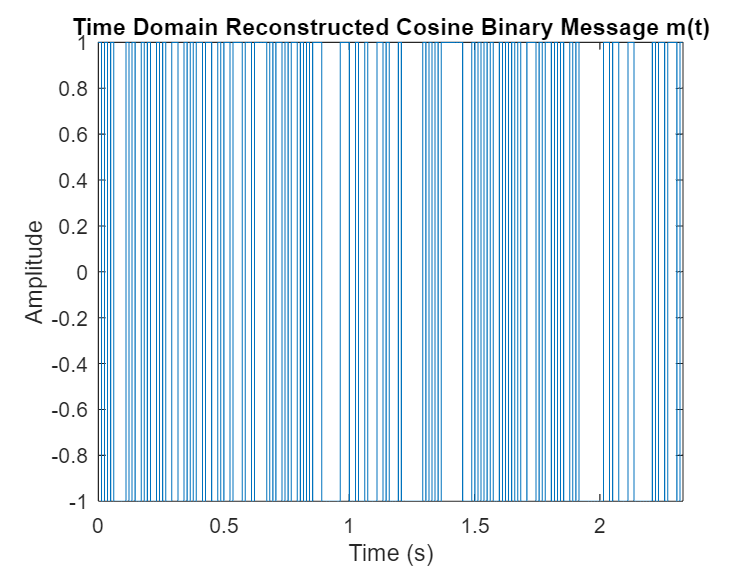

m_c_up = upsample(message_c*2-1, 2); m_c_up(2:2:end) = m_c_up(1:2:end);
t_up = upsample(t_dn, 2); t_up(2:2:end-1) = t_up(3:2:end); t_up(end) = max(t_up);
plot_time_graph(t_up, m_c_up)
title("Time Domain Reconstructed Cosine Binary Message m(t)")
saveas(gcf, "14. Time Domain Reconstructed Cosine Binary Message.png")

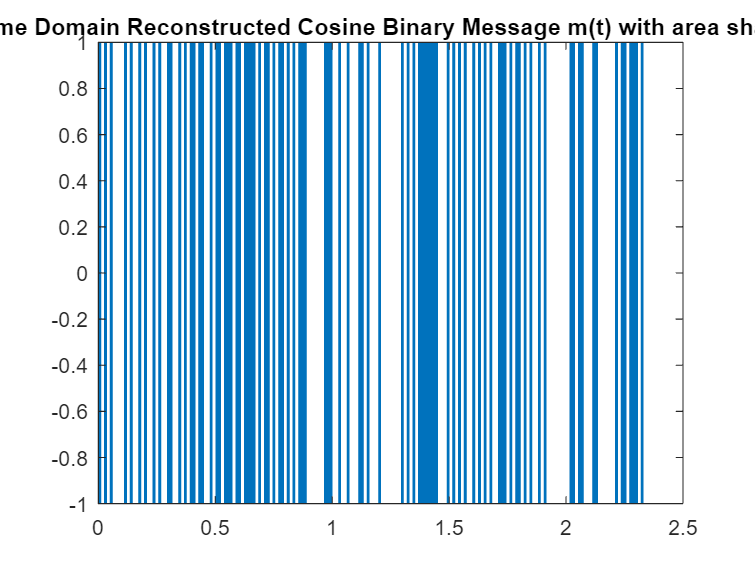


area(t_up, m_c_up, -1, 'LineStyle','none')
ylim([-1,1])
title("Time Domain Reconstructed Cosine Binary Message m(t) with area shaded")
saveas(gcf, "15. Time Domain Reconstructed Cosine Binary Message with area shaded.png")

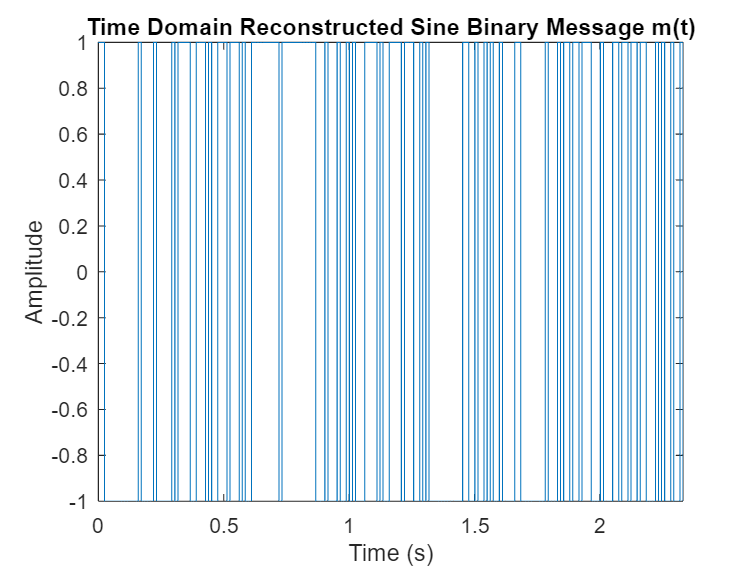

m_s_up = upsample(message_s*2-1, 2); m_s_up(2:2:end) = m_s_up(1:2:end);
t_up = upsample(t_dn, 2); t_up(2:2:end-1) = t_up(3:2:end); t_up(end) = max(t_up);
plot_time_graph(t_up, m_s_up)
title("Time Domain Reconstructed Sine Binary Message m(t)")
saveas(gcf, "14.5 Time Domain Reconstructed Sine Binary Message.png")

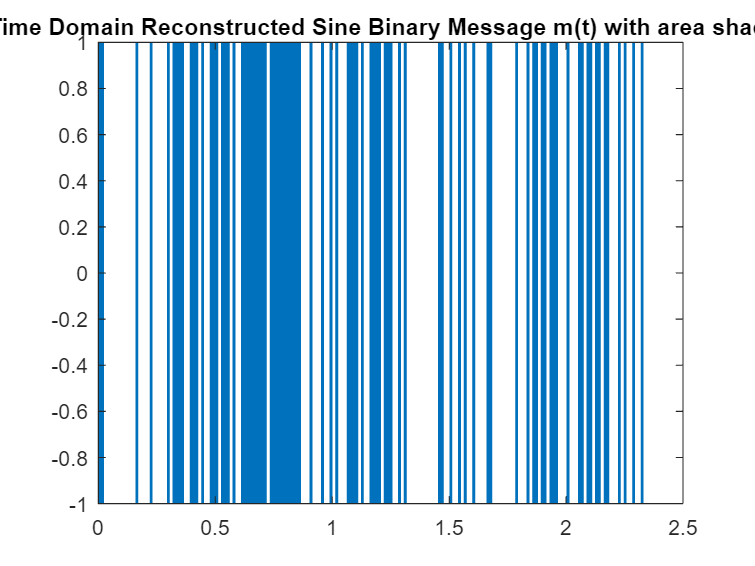


area(t_up, m_s_up, -1, 'LineStyle','none')
ylim([-1,1])
title("Time Domain Reconstructed Sine Binary Message m(t) with area shaded")
saveas(gcf, "15.5 Time Domain Reconstructed Sine Binary Message with area shaded.png")

function plot_time_graph(t, x)
    plot(t, x); xlabel('Time (s)'); ylabel('Amplitude')
    xlim([min(t), max(t)])
end